# Microchaos in a 6D mixed-mode SSM model

clearvars
close all
clc

In this notebook, we model the effects of **spatial discretization** on the dynamics of a **Furuta pendulum** stabilized by a **proportional–derivative (PD) controller** in the presence of **time delay **[1].

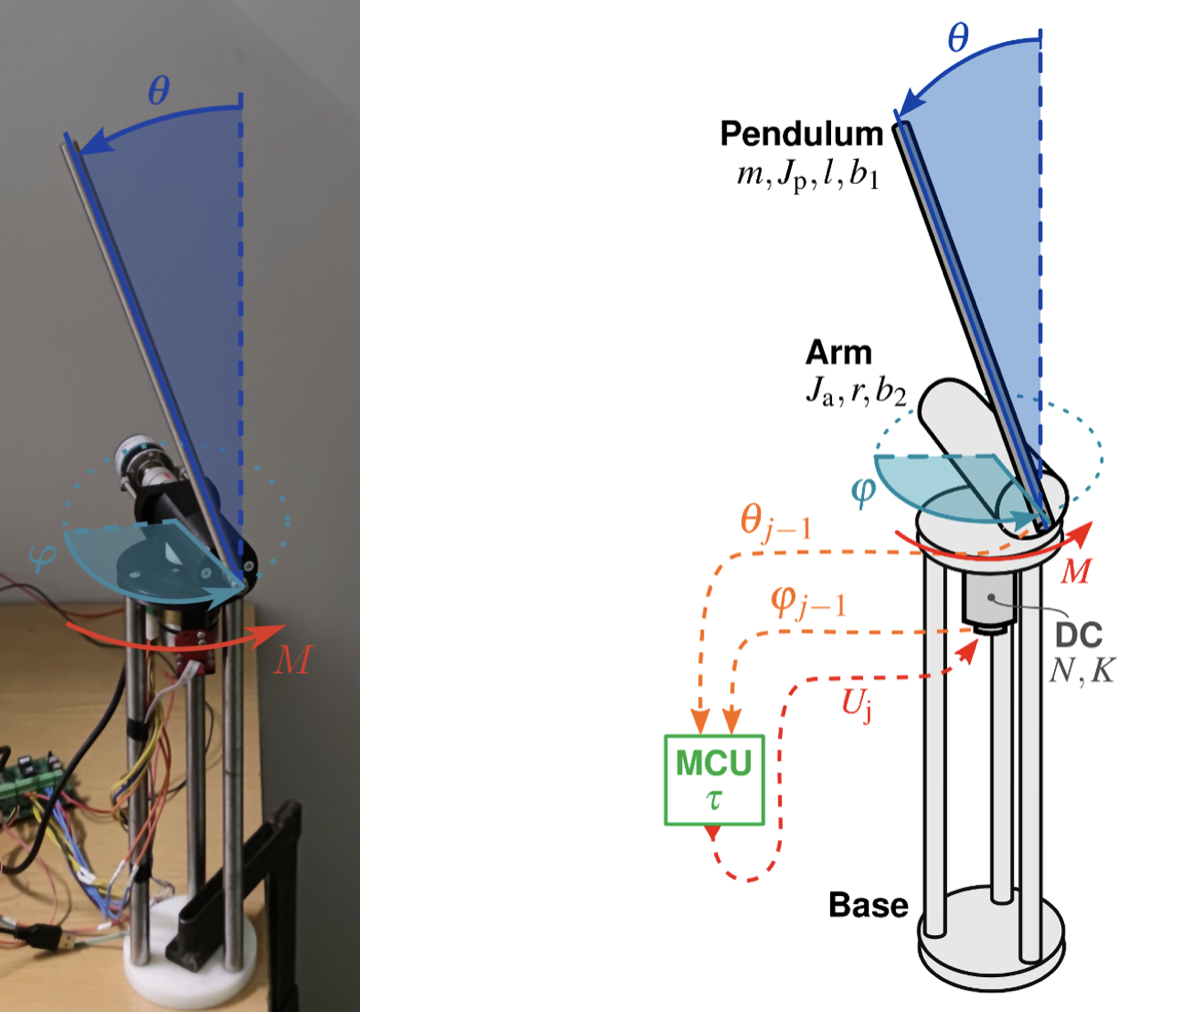                    

(Experiments conducted in Dept. Applied Mechanics @ BME)

Spatial discretization is found to induce the emergence of a **chaotic attractor** in the phase space of the system [3].

We investigate this by reducing the dynamics of the **Furuta pendulum**, stabilized about its **upright equilibrium**, to a **6D Spectral Submanifold (SSM)** that supports chaotic dynamics.

### References

[1] Vizi, M. B. & Stepan, G. “Digital Stability of the Furuta Pendulum Based on Angle Detection”. J. Vib. Control 30 (2024), 588–597.

[2] Xu, Z., Kaszas, B., Cenedese, M., Berti, G., Coletti, F. & Haller, G. “Data-Driven Modelling of the Regular and Chaotic Dynamics of an Inverted Flag from Experiments”. J. Fluid Mech. 987 (2024), R7.

[3] Stepan, G., Milton, J. G. & Insperger, T. “Quantization Improves Stabilization of Dynamical Systems with Delayed Feedback”. Chaos 27 (2017), 114306.

utilsDir = fullfile(pwd, 'utils');
assert(isfolder(utilsDir), ...
    'Cannot find utils folder at %s. Please cd to the correct directory.', utilsDir);

addpath(genpath(utilsDir));

projectRoot = fullfile(pwd, '..', '..');   
variousDir  = fullfile(projectRoot, 'Various');
assert(isfolder(variousDir), ...
    'Cannot find Various folder at %s.', variousDir);

addpath(genpath(variousDir));

installFile = fullfile(variousDir, 'install.m');
assert(isfile(installFile), ...
    'install.m not found in %s.', variousDir);

run(installFile);

SSMLearn: Data-driven Reduced Order Models for Nonlinear Dynamical Systems
License: GNUv3.0


SSMLearn successfully installed!
 
Checking SSMTool is installed...




figOpts = { ...
    'Interpreter',     'latex', ...
    'FontName',        'Helvetica', ...
    'FontSizeAxes',    25,   ... 
    'FontSizeLabels',  25,   ... 
    'FontSizeTitle',   20,   ... 
    'BackgroundColor', 'white', ...
    'Grid',            'on',  ...
    'AxesLineWidth',    2, ...
    'PlotLineWidth',    2, ...
    'Box',             'on'   ...
    'ScreenCoverage', 0.5 
};

# **Numerical Simulations** of the Furuta pendulum with Time Delay and Spatial Discretization

## Loading the chaotic time series

We numerically simulated 36 trajectories of the system, monitoring the angular displacement of the vertical arm.

All trajectories were initialized within a small neighborhood of the fixed point corresponding to the upright equilibrium, and each exhibits chaotic behavior, being attracted to the microchaotic attractor.

folder = 'NumericalSimulations';
load(fullfile(folder,'xDataKp_15.5_Kd_5.45.mat'),'xData');
nTraj = size(xData, 1);

## Correlation dimension

We estimate the fractal dimension of the chaotic attractor

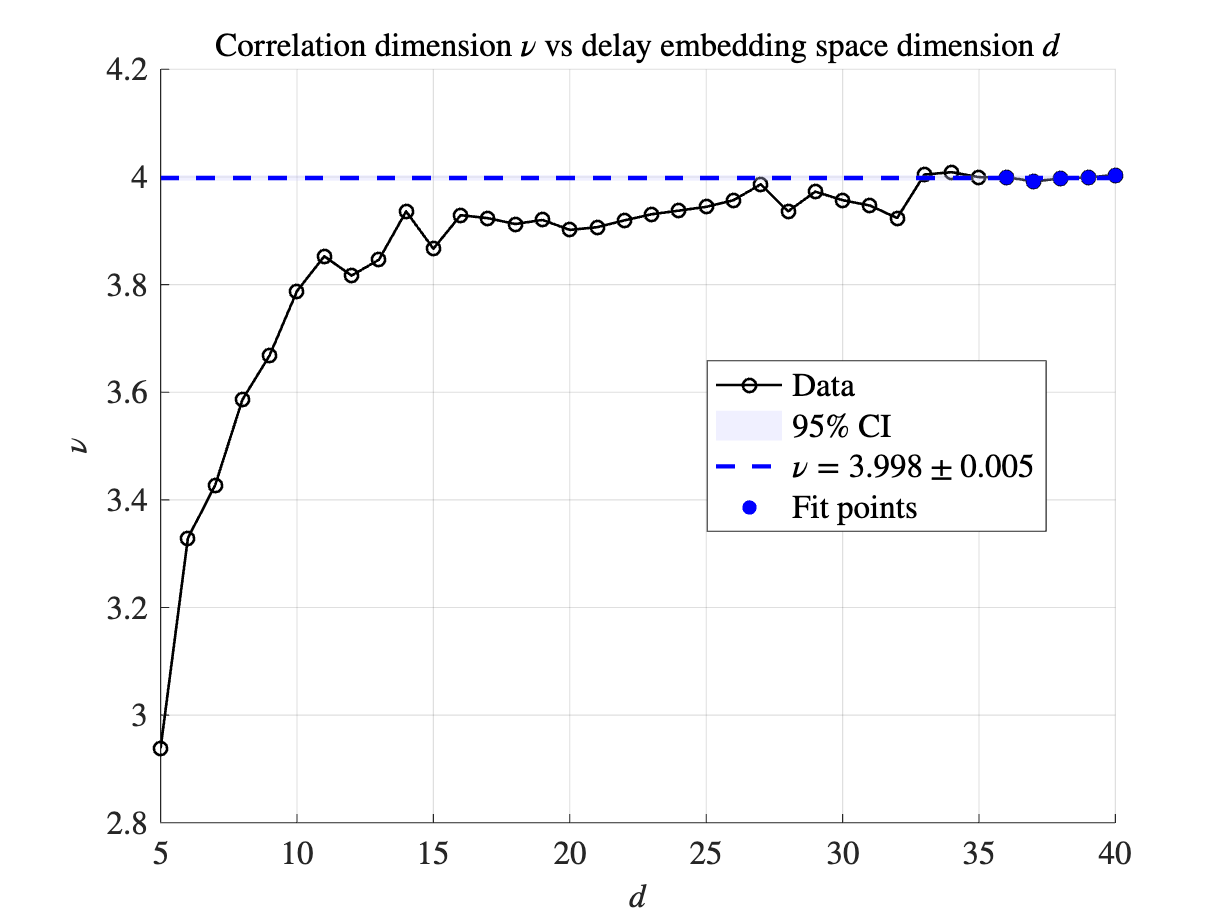

dSweep = 5:40;
nTraj_nu = 5; 
tau = 6;
slicexData = 10000; %last points to be used for CorrDim
plotCorrDim(xData, slicexData, dSweep, tau, nTraj_nu)

## Manifold fitting

Owing to the oscillatory nature of the system, the eigenvalues of the linearized dynamics at the upright equilibrium appear in complex conjugate pairs. Consequently, the dimension of any mixed-mode Spectral Submanifold (SSM) that contains the chaotic attractor must be an even integer exceeding the fractal dimension of the attractor, which is around 3.9. Note that the SSM dimension need not be the smallest even integer exceeding 3.9 (i.e. 4), which is a necessary but not sufficient condition for embedding the chaotic attractor within the SSM.

We select d=6 and construct a six-dimensional mixed-mode SSM from delay-embedded observable data.

% Parameters
% Parameters
SSMDim = 6;
overEmbed = 125;
sliceInt = [0, 70]; 
SSMOrder = 1;
ROMOrder = 3;
lag = 22;

% Train and test
indTrain = [35,36];
indTest = [34, 1];

%Coordinates embedding
[yData, opts_embd] = coordinatesEmbedding(xData, SSMDim, 'OverEmbedding', overEmbed, 'TimeStepping', lag);

The 138 embedding coordinates consist of the measured state and its 137 time-delayed measurements.


yDataTrunc = sliceTrajectories(yData, sliceInt);

%SSM map identification
IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder);
etaDataTrunc = projectTrajectories(IMInfo, yDataTrunc);

## Reduced order model

We use polynomials to provide a smooth ODE approximation to the non-smooth dynamics reduced to the SSM of the full system. 

%fitting the dynamics 
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:), 'R_PolyOrd', ROMOrder,'MaxIter',2e3);

Estimation of the reduced dynamics...  Done. 


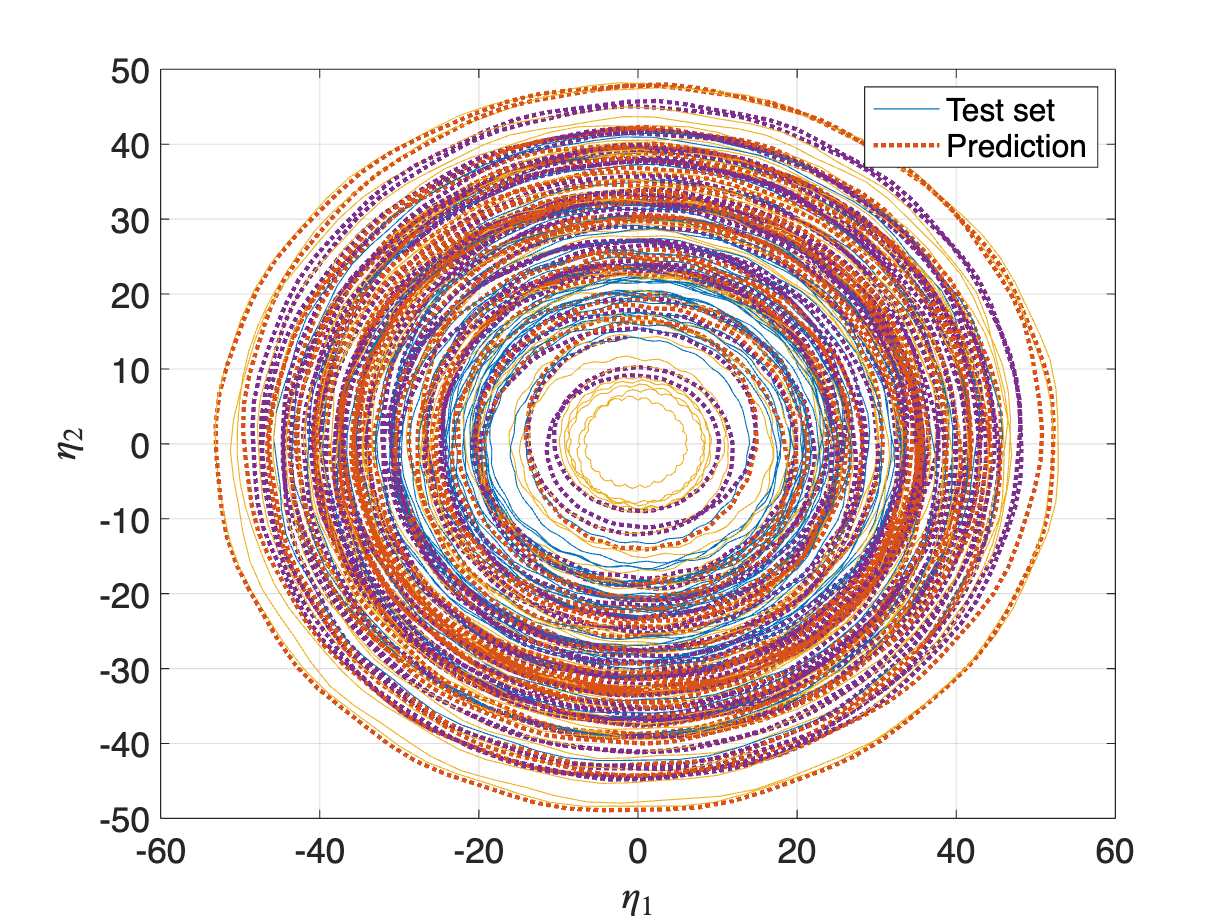


[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yDataTrunc);
% visualizing the test set in the reduced coordinates
plotReducedCoordinates(etaDataTrunc(indTest,:), etaRec(indTest,:))
legend({'Test set', 'Prediction'})


linearPart = RDInfo.reducedDynamics.coefficients(1:SSMDim, 1:SSMDim);
[~,Drd] = eig(linearPart);
Drd

Drd =    0.1783 +62.2916i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.1783 -62.2916i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3285 + 3.4183i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.3285 - 3.4183i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2806 + 2.9434i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.2806 - 2.9434i


## Testing — Time Prediction of Unseen Trajectories

To evaluate the generalization performance of the reduced model, we test its ability to predict the temporal evolution of trajectories that were not part of the training data. Using the polynomial approximation of the reduced dynamics, we integrate the reduced coordinates forward in time. These predictions are then mapped back to the physical state space through the SSM parametrization, providing the reconstructed angular displacement of the pendulum’s vertical arm.

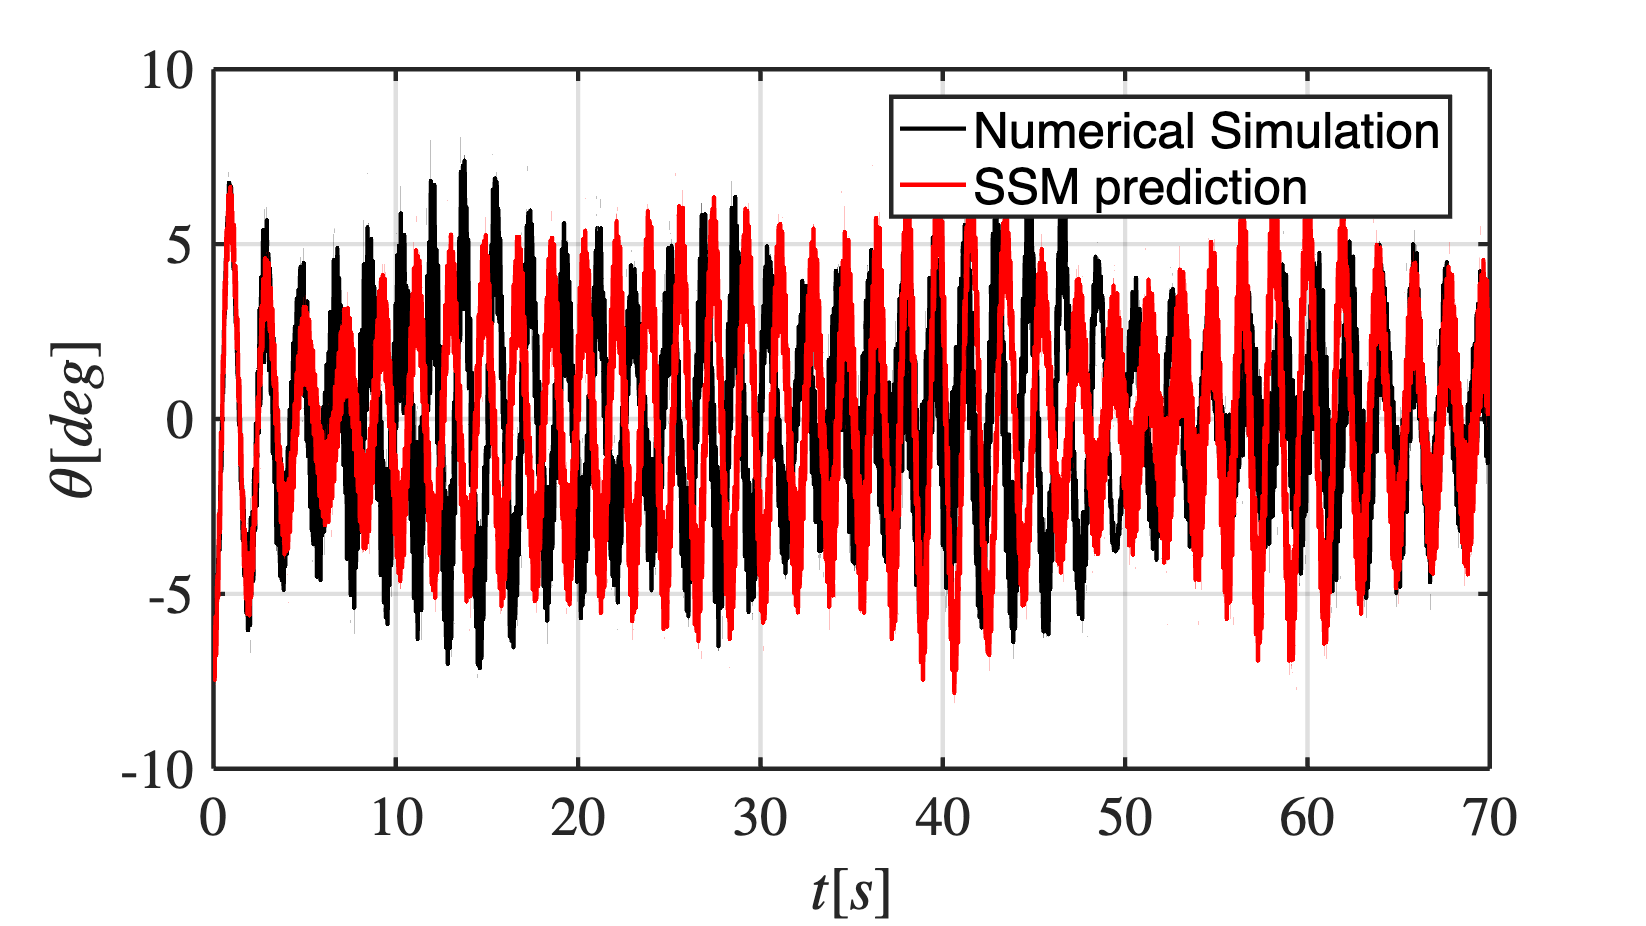

% Trajectory - comparison
MyCustomFigure(figOpts{:});  
plot(yDataTrunc{indTest(1),1}(1,:), yDataTrunc{indTest(1),2}(1,:), 'k-','DisplayName','Numerical Simulation');
plot(yRec{indTest(1),1}(1,:), yRec{indTest(1),2}(1,:), 'r-','DisplayName','SSM prediction' );
legend('Location','best');
xlabel('$t [s]$');
ylabel('$\theta [deg]$');
xlim(sliceInt);

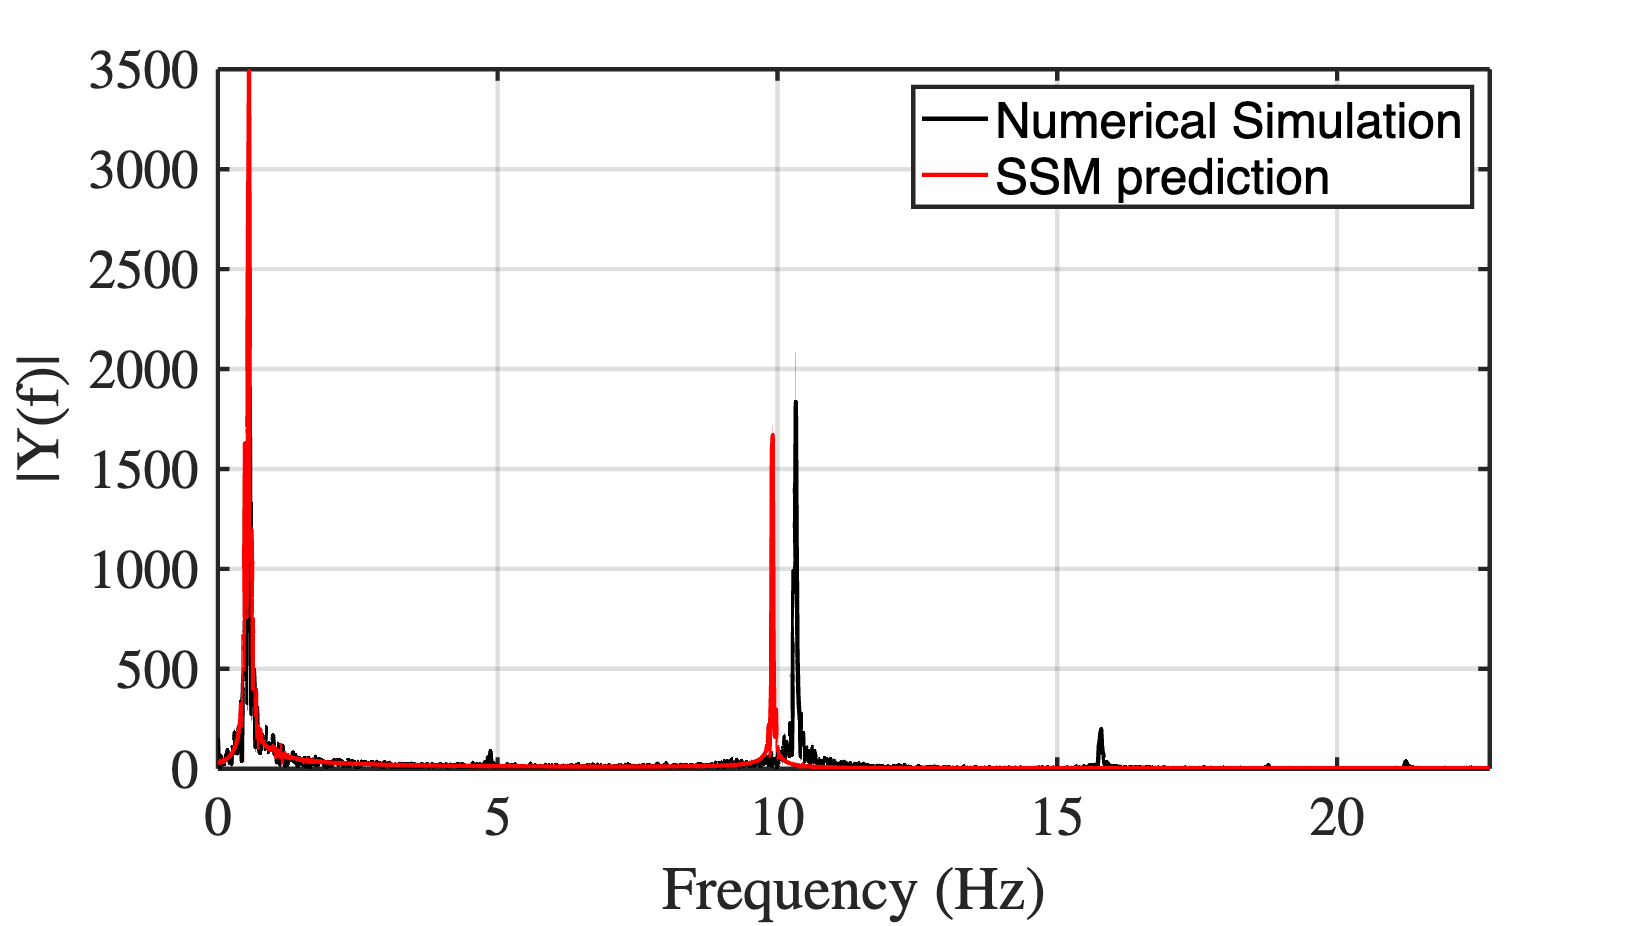


% Frequency spectrum - comparison
y1 = yDataTrunc{indTest(1),2}(1,:);
y2 = yRec{indTest(1),2}(1,:);
dt = yRec{1,1}(2) - yRec{1,1}(1);
Fs = 1/dt;

Y1 = fft(y1);
Y2 = fft(y2);
L = numel(y1);
f = Fs*(0:(L/2))/L;

MyCustomFigure(figOpts{:});
plot(f, abs(Y1(1:L/2+1)), 'k', f, abs(Y2(1:L/2+1)), 'r');
xlim([0 Fs/2]);
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
legend('Numerical Simulation', 'SSM prediction');
grid on; box on;

## Testing — Probability Density Functions of reduced coordinates

Since trajectory prediction is unreliable for chaotic systems due to their sensitivity to initial conditions, our evaluation focuses on long-term statistics. Specifically, we compare the probability density functions (PDFs) of the reduced coordinates.

Assuming the system is ergodic, we interchange temporal and ensemble averages to estimate the invariant measure of the attractor, following the procedure described in [2].

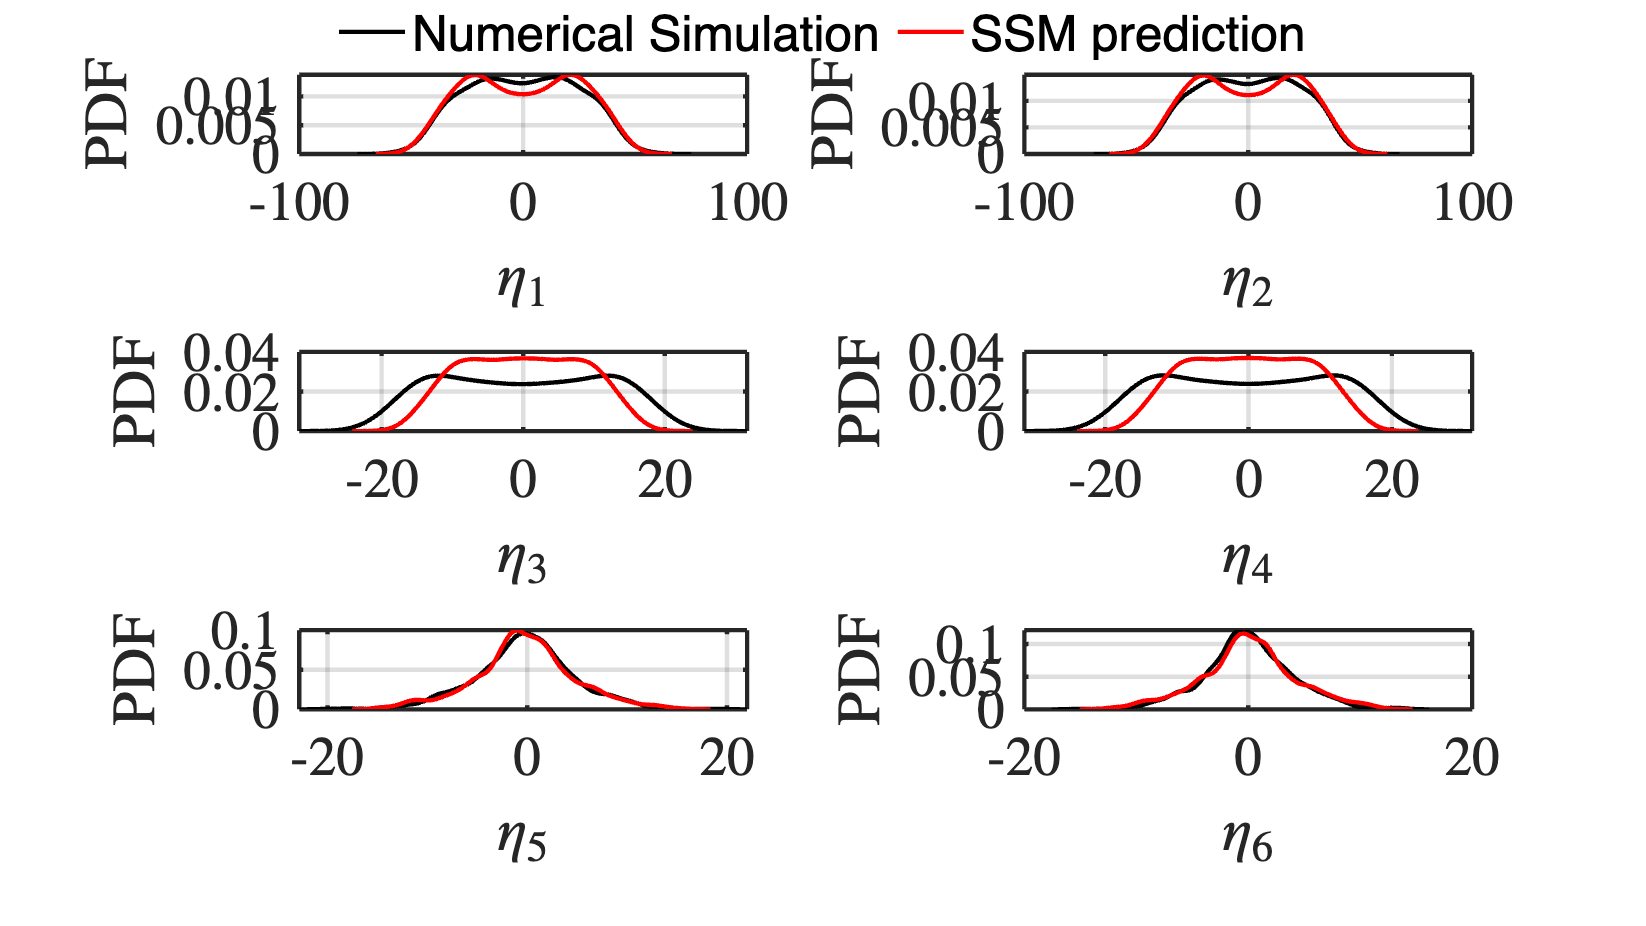

dataExp = [];
dataPred = [];

for idx = 1:numel(indTrain)
    dataExp  = [dataExp, etaDataTrunc{indTrain(idx),2}(:,:)];
    dataPred = [dataPred, etaRec{indTrain(idx),2}(:,:)];
end

legendLabels = {'Numerical Simulation','SSM prediction'};
MyCustomFigure(figOpts{:}, 'SubPlot', [3,2]);
for i = 1:6
    hSub = subplot(3,2,i);     
    [fExp,  xiExp]  = ksdensity(dataExp(i,:),  'NumPoints', 200);
    [fPred, xiPred] = ksdensity(dataPred(i,:), 'NumPoints', 200);
    
    h1 = plot(xiExp,  fExp,  'k-'); 
    hold on; grid on;
    h2 = plot(xiPred, fPred, 'r-');
    
    xlabel(sprintf('$\\eta_{%d}$', i));
    ylabel('PDF');
end

lgd = legend([h1, h2], legendLabels, 'Box','off','Orientation','horizontal','NumColumns', 2, 'Position',[0.35 0.94 0.3 0.05]); 

## Visualizing the attractor in the reduced space

Here we visualize the chaotic attractor in the reduced space. 

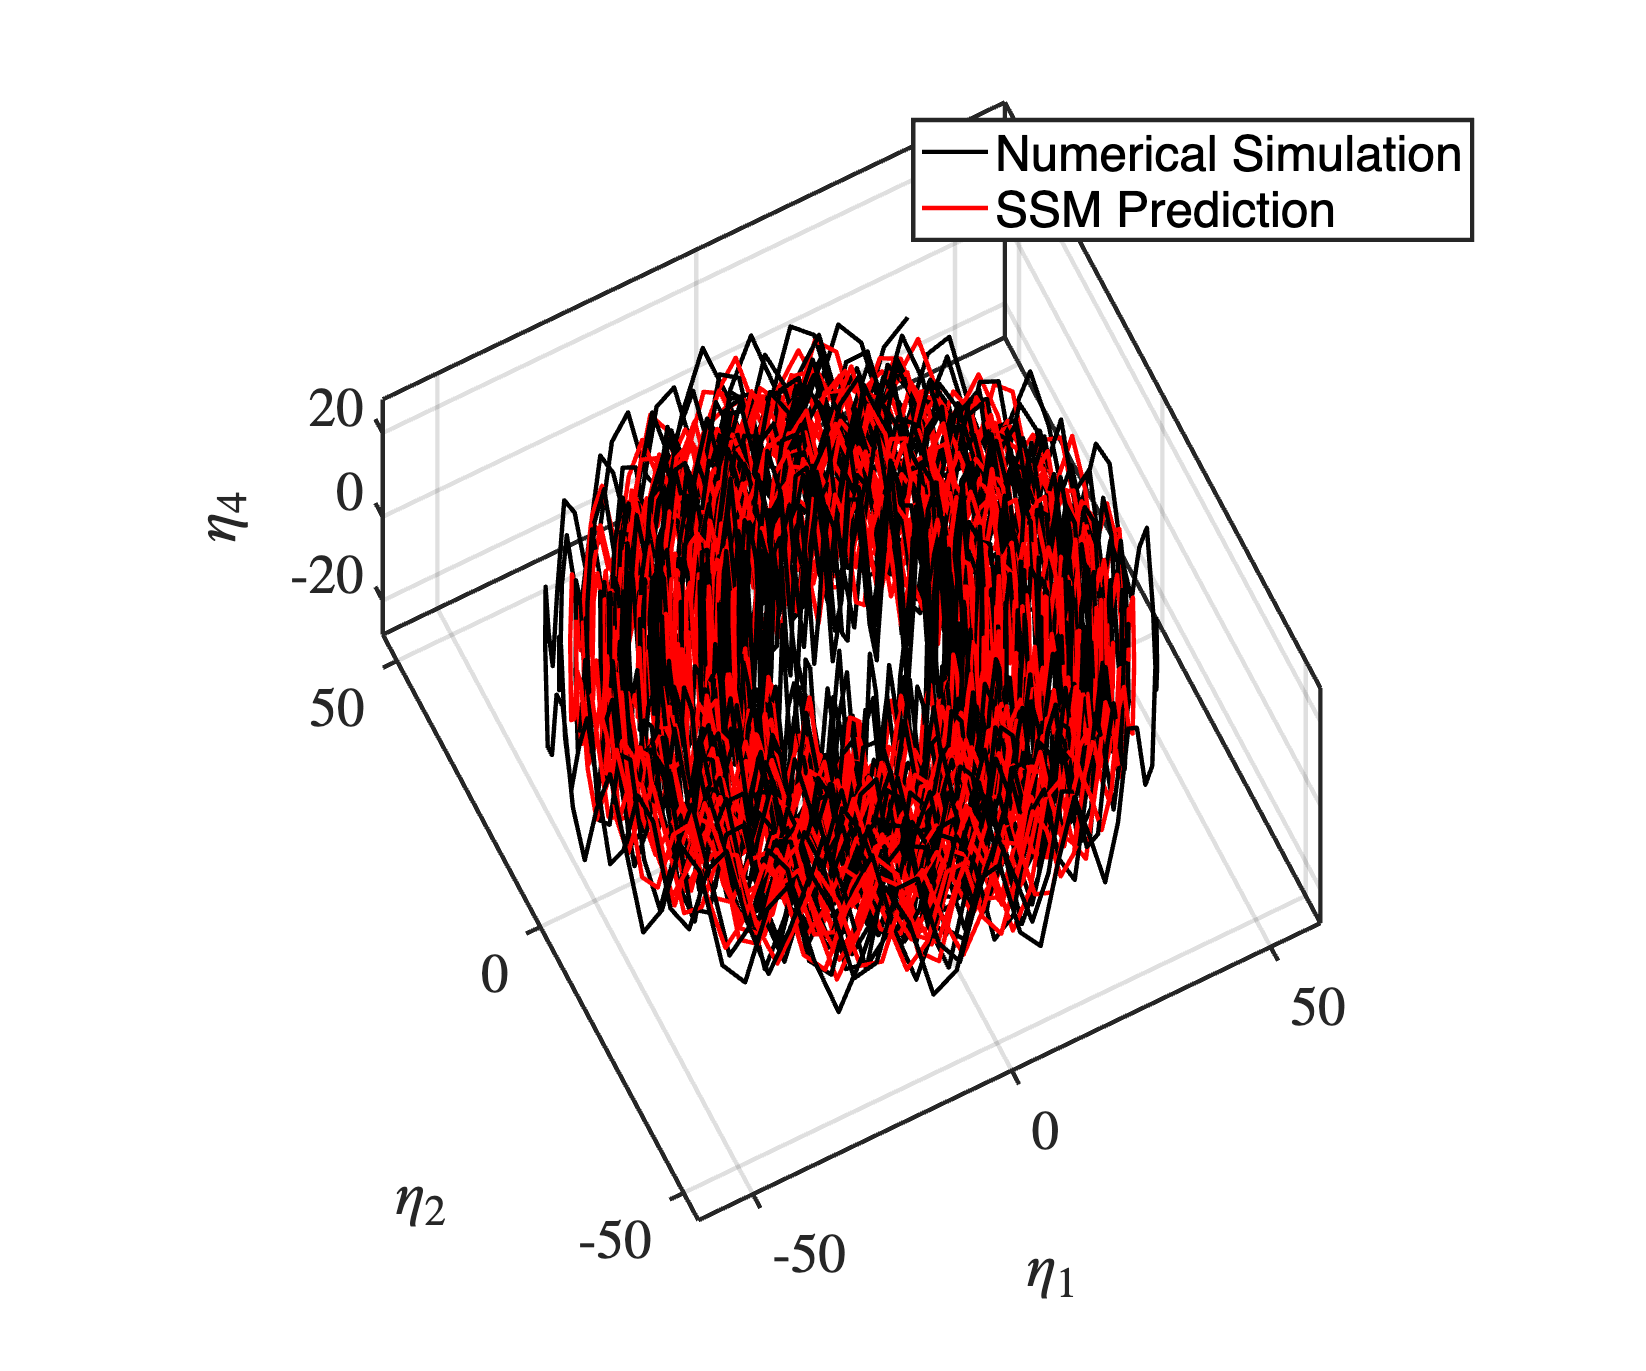

MyCustomFigure(figOpts{:});
set(gcf,'Units','pixels','Position',[100 100 1200 1000]);

[i,j,k] = deal(1,2,4);
t = etaDataTrunc{1,1};
tStartPlot = 20;
startCol = max(find(t >= tStartPlot,1),1);
etaExp = etaDataTrunc{indTest(2),2}(:,startCol:end);
etaPred = etaRec{indTest(2),2}(:,startCol:end);

ax = gca; hold(ax,'on'); grid(ax,'on');
h1 = plot3(ax,etaExp(1,:),etaExp(2,:),etaExp(3,:),'k-');
h2 = plot3(ax,etaPred(1,:),etaPred(2,:),etaPred(3,:),'r-');

xlabel(ax,sprintf('$\\eta_{%d}$',i));
ylabel(ax,sprintf('$\\eta_{%d}$',j));
zlabel(ax,sprintf('$\\eta_{%d}$',k));

view([-26.9 70.3]); axis(ax,'padded'); axis(ax,'vis3d');
legend(ax,[h1 h2],{'Numerical Simulation','SSM Prediction'},'Location','northeast');

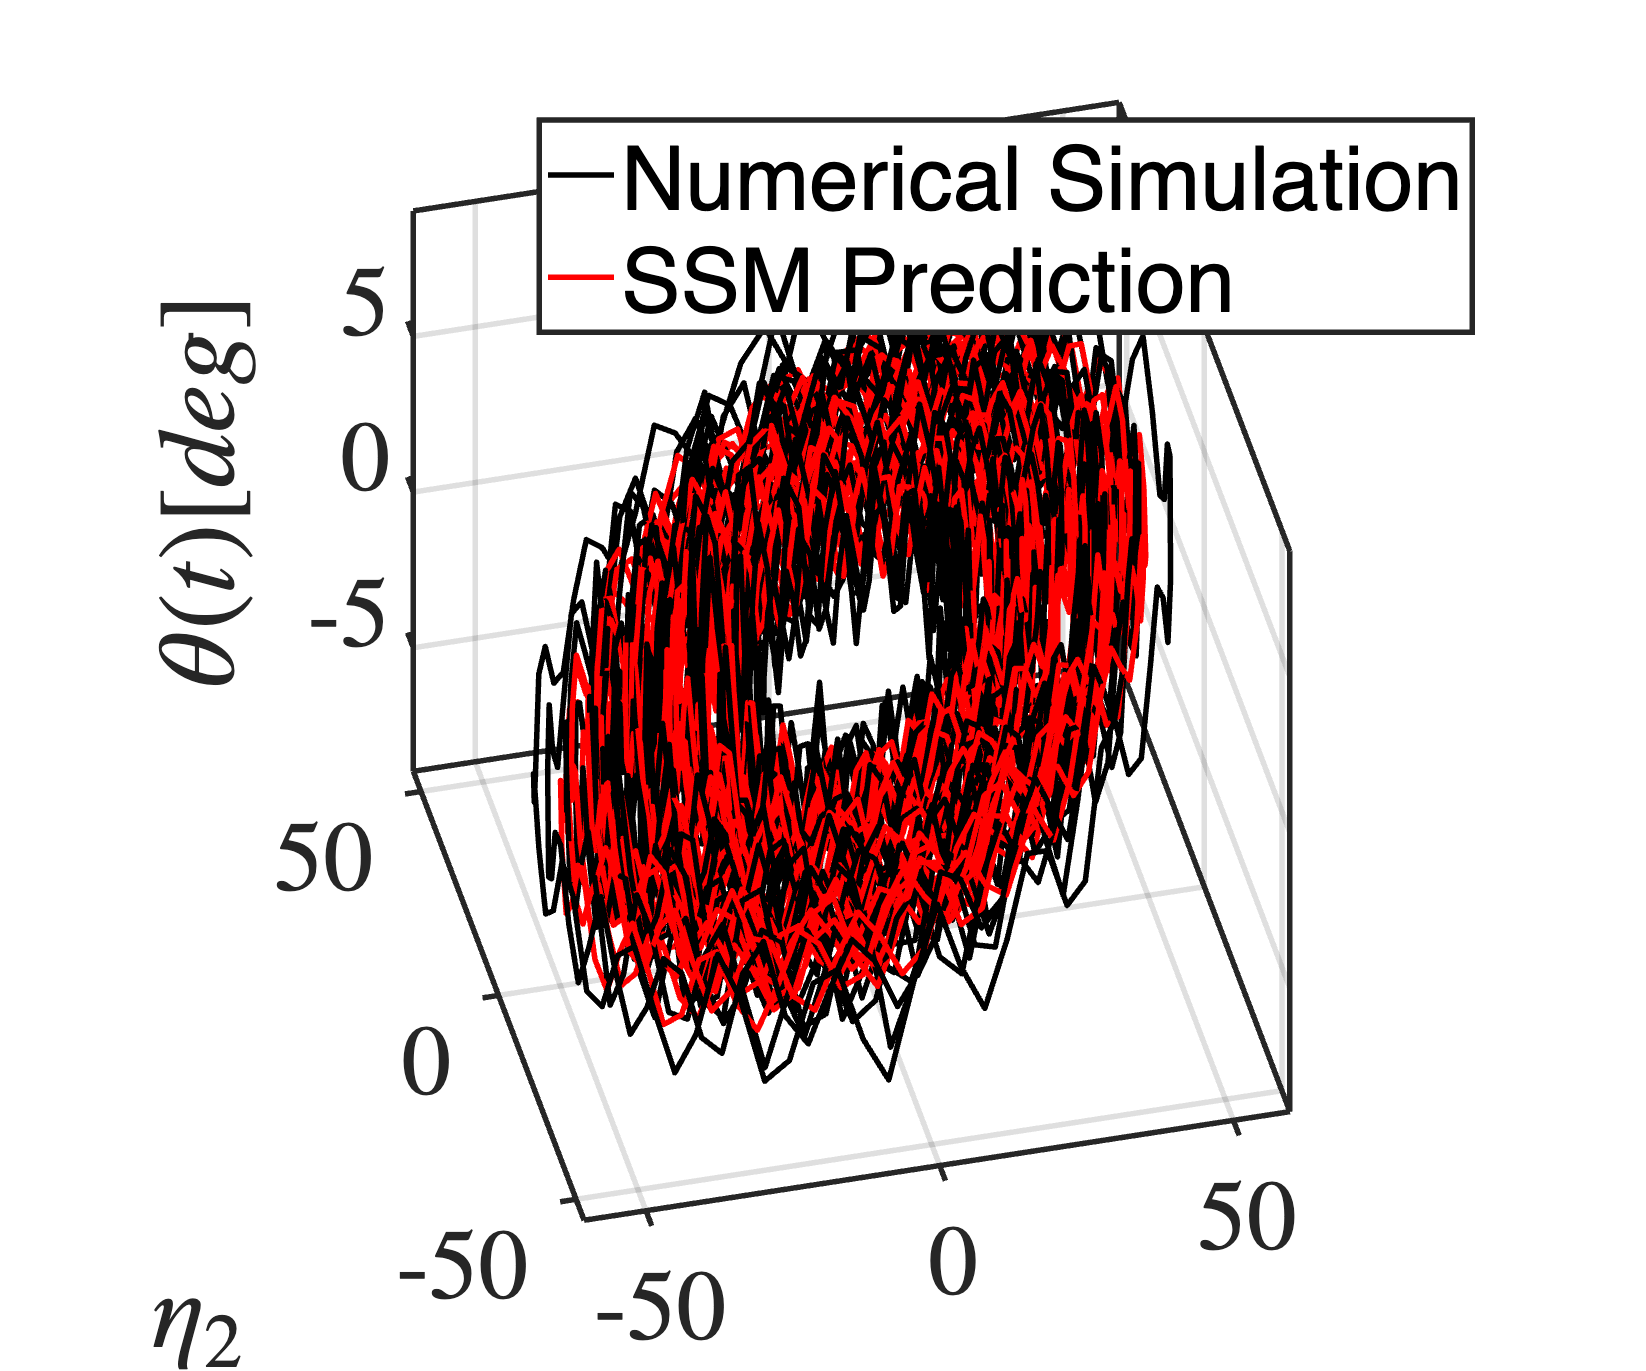

figOpts = { ...
    'Interpreter',     'latex', ...
    'FontName',        'Helvetica', ...
    'FontSizeAxes',    45,   ... % tick labels
    'FontSizeLabels',  45,   ... % axis labels
    'FontSizeTitle',   45,   ... % titles
    'BackgroundColor', 'white', ...
    'Grid',            'on',  ...
    'AxesLineWidth',    2.5, ... %numeric line width for axes box (default: 0.5)
    'PlotLineWidth',    2.5, ...%numeric default line width for plotted data (default: 0.5)
    'Box',             'on'   ...
    'ScreenCoverage', 0.5 %fraction of screen to cover [0,1] (default: 0.8)
};

MyCustomFigure(figOpts{:});
set(gcf,'Units','pixels','Position',[100 100 1200 1000]);

[i,j] = deal(1,2);
t = etaDataTrunc{1,1};
tStartPlot = 20;
startCol = max(find(t >= tStartPlot,1),1);
etaExp = etaDataTrunc{indTest(2),2}(:,startCol:end);
etaPred = etaRec{indTest(2),2}(:,startCol:end);
yExp = yDataTrunc{indTest(2),2}(1,startCol:end);
yPred = yRec{indTest(2),2}(1,startCol:end);

ax = gca; hold(ax,'on'); grid(ax,'on');
h1 = plot3(ax,etaExp(i,:),etaExp(j,:),yExp,'k-');
h2 = plot3(ax,etaPred(i,:),etaPred(j,:),yPred,'r-');

xlabel(ax,sprintf('$\\eta_{%d}$',i));
ylabel(ax,sprintf('$\\eta_{%d}$',j));
zlabel(ax,sprintf('$\\theta(t) [deg]$',k));

view([346.4 39.5]); axis(ax,'padded'); axis(ax,'vis3d');
legend(ax,[h1 h2],{'Numerical Simulation','SSM Prediction'},'Location','northeast');

## Lyapunov Exponent estimation 

Here, we advect full-system trajectories initialized in a small neighborhood of the origin and estimate the Lyapunov exponent of the chaotic attractor. By tracking how the norm (here, the Euclidean norm) of a small perturbation $\delta (0)$ to an initial condition evolves in time, one can obtain an estimate of the largest Lyapunov exponent, $\lambda $, as $\delta (t))/ \delta (0) \sim e^{\lambda t}$. Numerical simulations offer precise control over the placement and magnitude of initial perturbations, in contrast to experimental settings, where such control is typically limited.

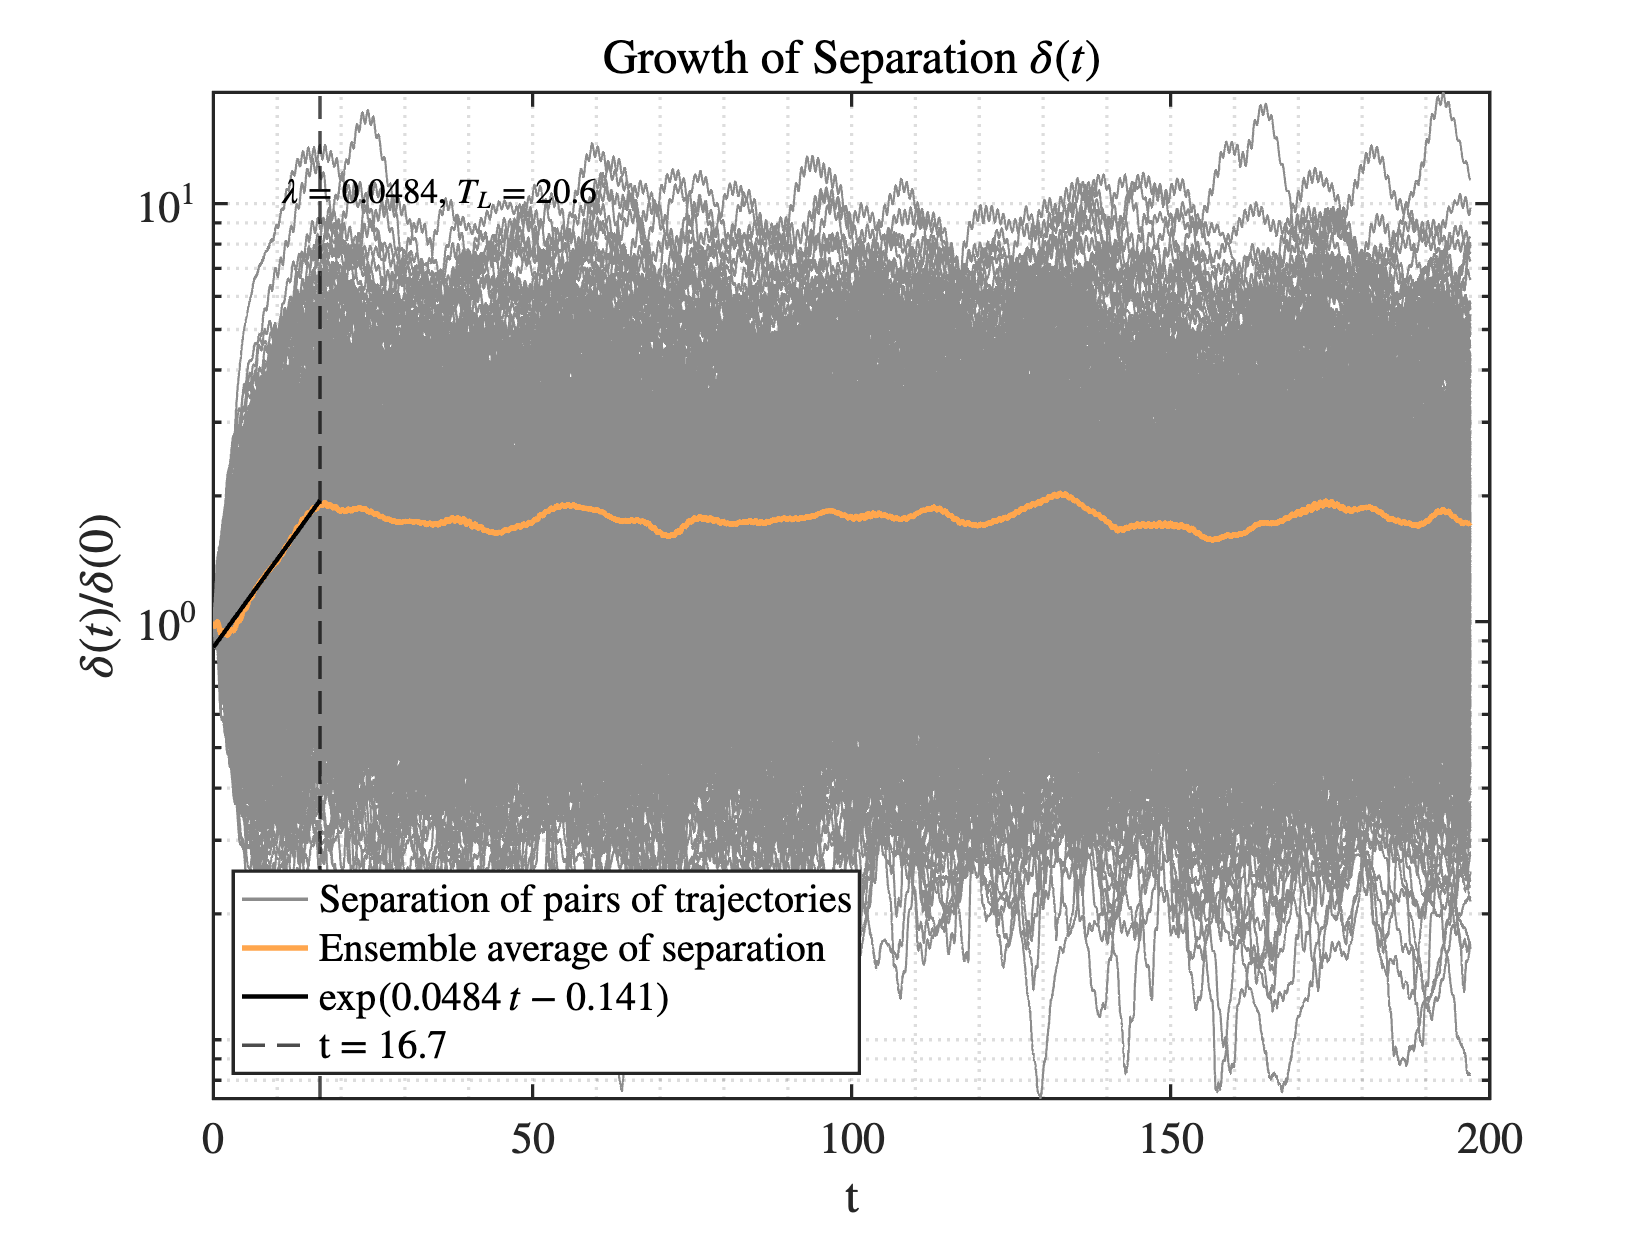

ans = 0.0484

LyapunovExponentInteractive(yData, 16.7)

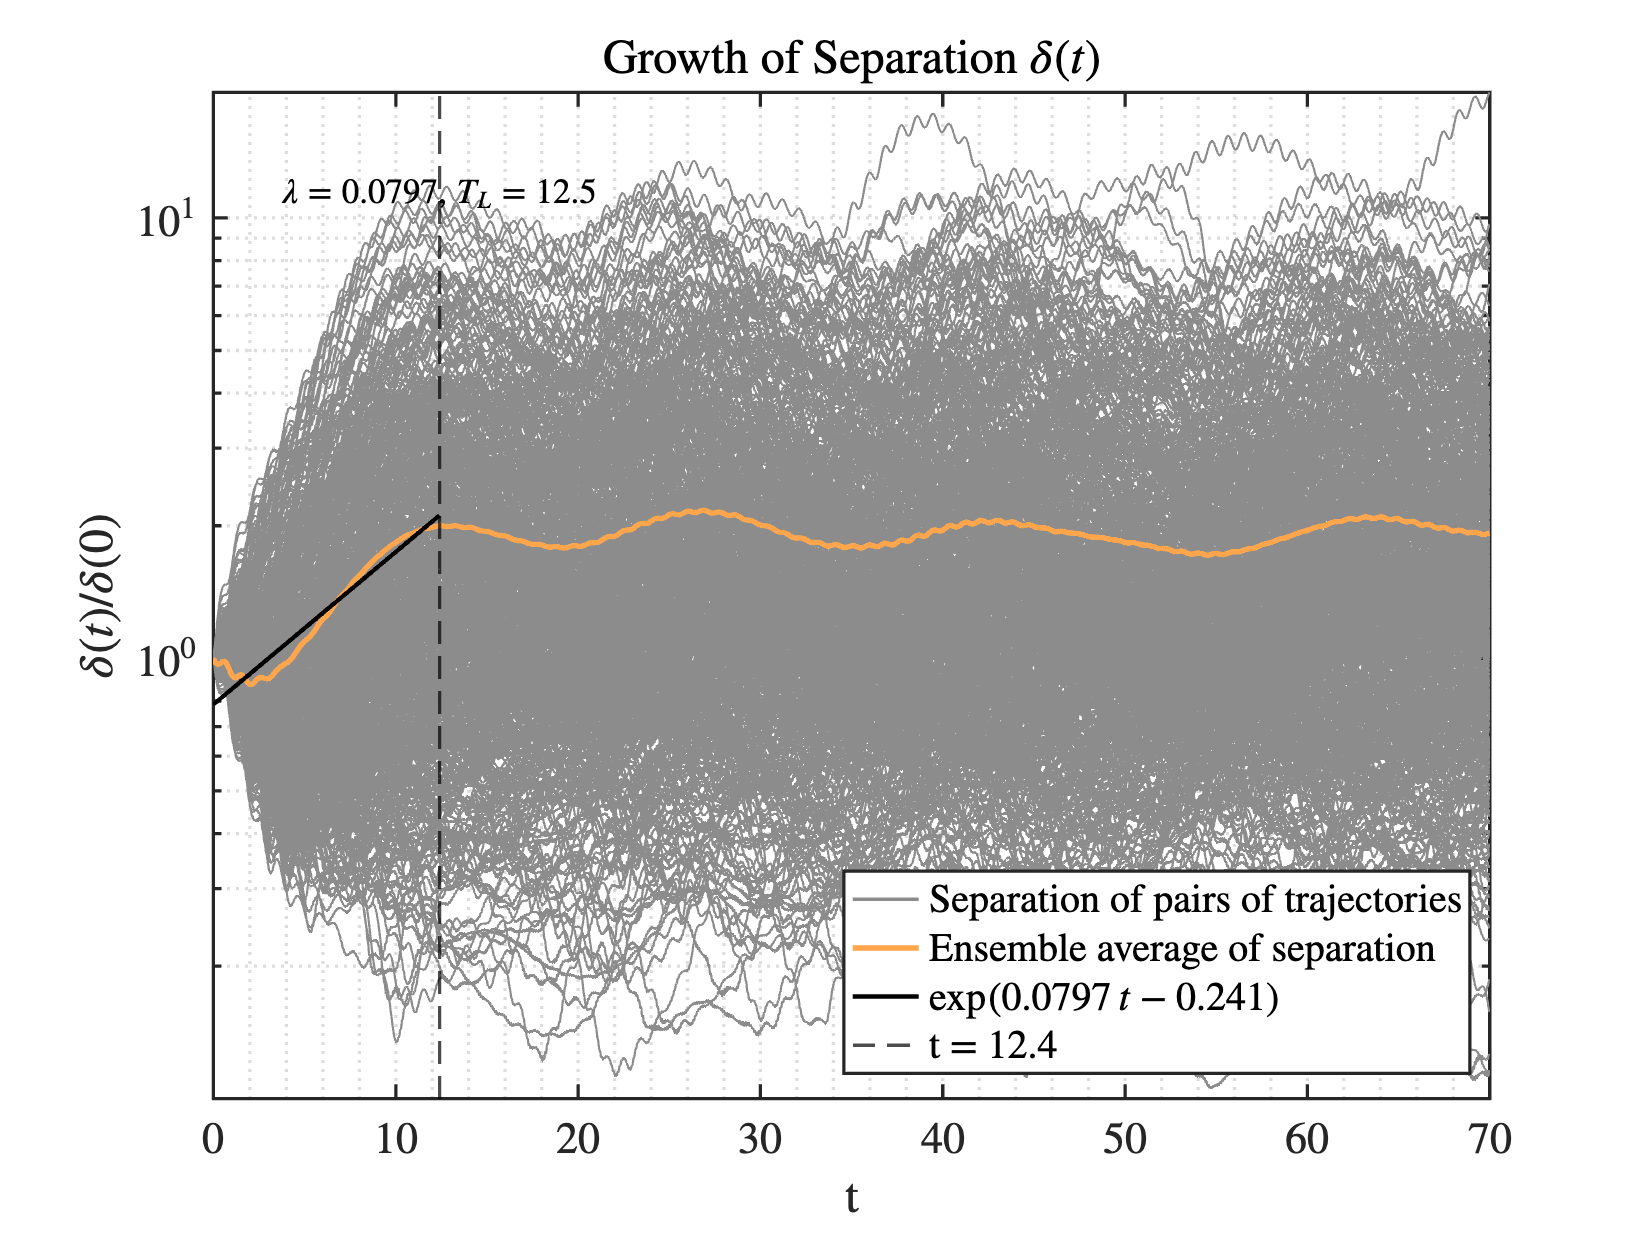

ans = 0.0797

LyapunovExponentInteractive(yRec, 12.4)

%Save structs
save(fullfile(folder,'IMInfo.mat'),'IMInfo');
save(fullfile(folder,'RDInfo.mat'),'RDInfo');

# **Experiments** of the Furuta pendulum with Time Delay and Spatial Discretization  

We now repeat the same analysis on experimental data collected from the Furuta pendulum at Applied Mechanics Dept. (Budapest Institute of Technology and Economics) stabilized by a PID controller with delayed feedback and spatial discretization matching the ADC (analog-to-digital converter)/DAC(digital-to-analog converted) hardware resolution.

## Loading the chaotic time series

We run three long experimental trajectories of the Furuta pendulum under PID control, tracking the system observable (i.e. angular displacement) throughout the motion. The two longest trajectories are used to train the SSM model, taking advantage of the chaotic attractor’s topological transitivity: longer trajectories provide more complete and informative coverage of the attractor’s structure.

clearvars -except figOpts outputFolder
folder = 'Experiments';
load(fullfile(folder,'xDataKp_25_Kd_6.mat'),'xData');
nTraj = size(xData, 1);

## Correlation dimension

We estimate the fractal dimension of the chaotic attractor

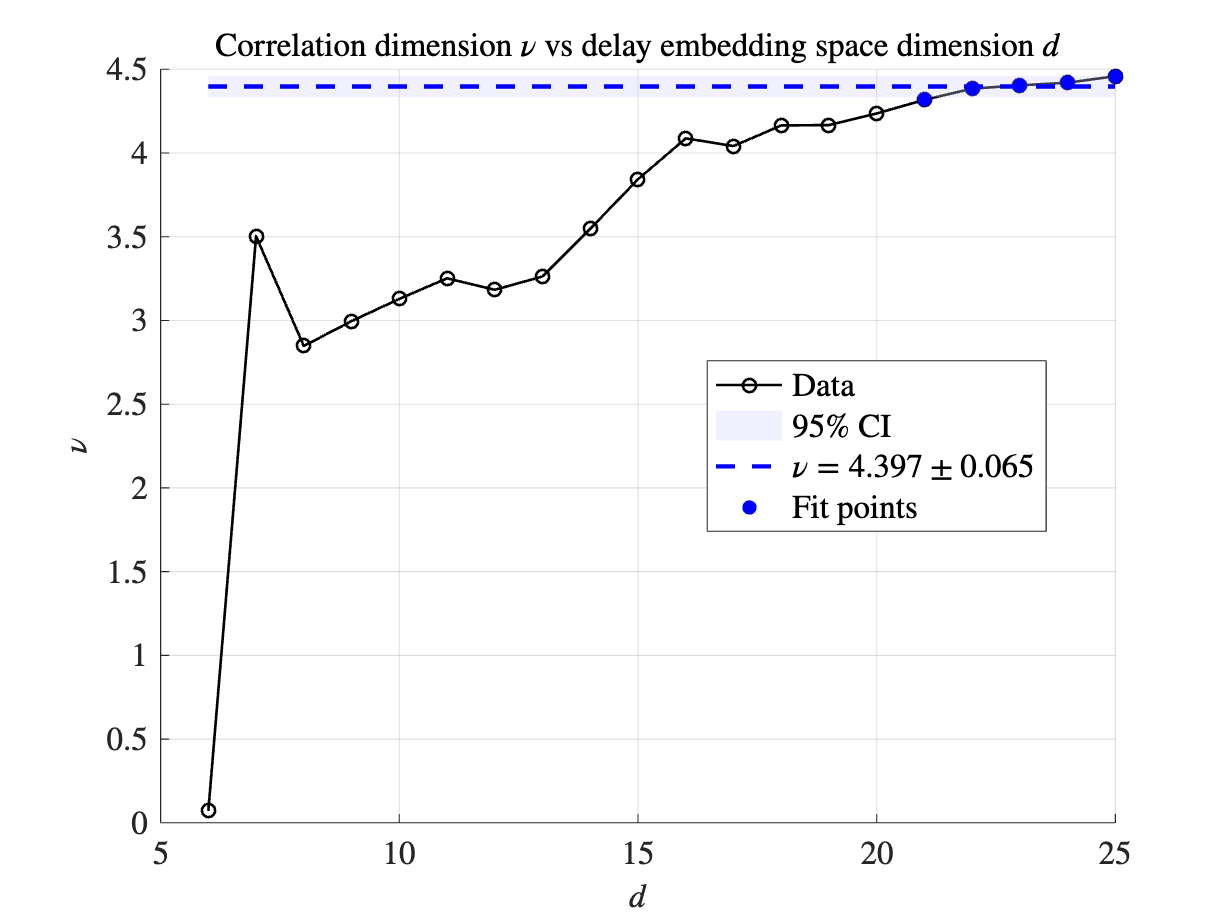

dSweep = 6:25;
nTraj_nu = 6;
tau = 5; 
slicexData = 10000; %last points to be used for CorrDim 
plotCorrDim(xData, slicexData, dSweep, tau, nTraj_nu)

## Manifold fitting

We construct a six-dimensional mixed-mode SSM from delay-embedded observable data.k

% Parameters
SSMDim = 6;
overEmbed = 75;
sliceInt = [1, inf]; 
SSMOrder = 1;
lag = 4;

% Train and test
indTrain = [27,28];
indTest = [11];

%Coordinates embedding
[yData, opts_embd] = coordinatesEmbedding(xData, SSMDim, 'OverEmbedding', overEmbed, 'TimeStepping', lag);

The 88 embedding coordinates consist of the measured state and its 87 time-delayed measurements.


yDataTrunc = sliceTrajectories(yData, sliceInt);

%SSM map identification
IMInfo_temp = IMGeometry(yDataTrunc(indTrain,:), SSMDim, 1);
etaDataTrunc = projectTrajectories(IMInfo_temp, yDataTrunc);
IMInfo = IMGeometry(yDataTrunc(indTrain,:), SSMDim, SSMOrder, 'reducedCoordinates', etaDataTrunc(indTrain,:));

## Reduced order model

We approximate the dynamics reduced to the SSM as a discrete mapping using radial basis functions (RBFs) with linear kernel instead of polynomials, as RBFs were found more accurate by [2]. The next-step prediction for the reduced coordinate $$\mathbf{\eta}$$ is written as


$$\eta_{n+1} =F\left(\eta \;\right)=\sum_{i=1} C_i k\left(||\;\eta_n -\eta_i ||\right),$$


where $k$  is a radial kernel (taken as the identity), and $\eta_i$ are the reduced coordinates from the training data. The coefficients $C_i$ are obtained via linear regression and subsequently used to evaluate the reduced dynamics.

eta_n = [];
eta_n_plus_1 = [];

for iTraj = indTrain
    eta_n = [eta_n, etaDataTrunc{iTraj,2}(:, 1:end-1);];
    eta_n_plus_1 = [eta_n_plus_1, etaDataTrunc{iTraj,2}(:, 2:end);];
end

rbfInterpolator = RBF_interpolator(eta_n, eta_n_plus_1);

## Testing — Time Prediction of Unseen Trajectories

To test the SSM model, we use the discrete RBF approximation of the dynamics reduced to the SSM. By repeatedly applying this map, we evolve the projected initial conditions of the test trajectories onto the reduced space forward in time. The predicted reduced states are then mapped back to the physical coordinates through the SSM parametrization, reconstructing the corresponding predicted physical motion of the system.

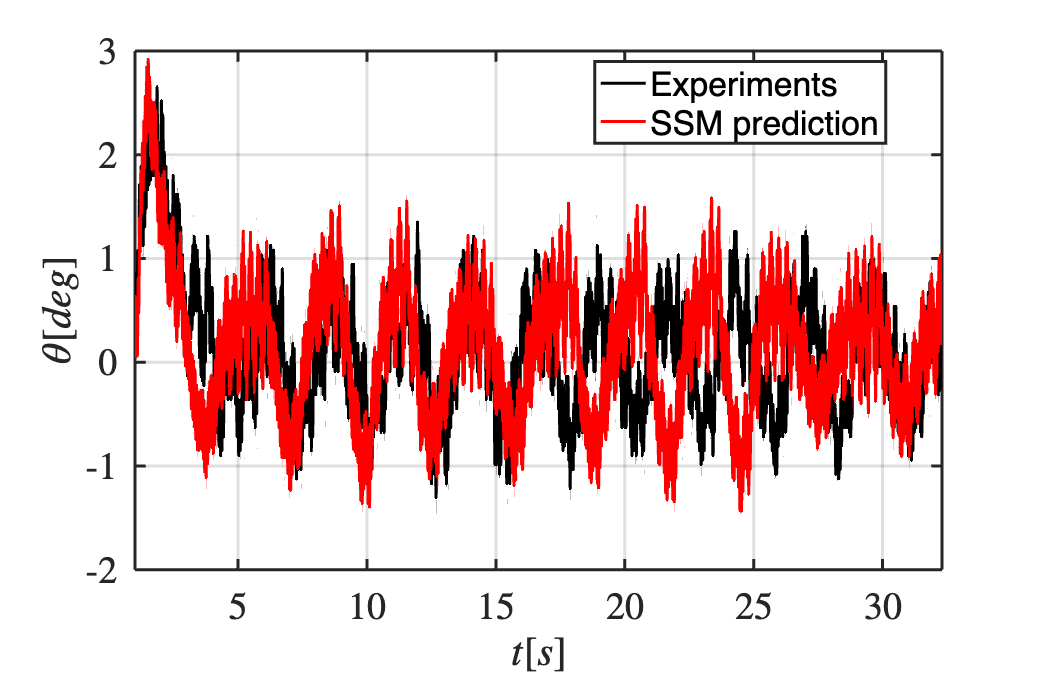

etaRec = cell(nTraj,2);
yRec = cell(nTraj,2);
for iTraj = 1:nTraj
    etaRec{iTraj, 1} = etaDataTrunc{iTraj, 1};    
    predicted_ = [etaDataTrunc{iTraj, 2}(:,1)];
    length = size(etaDataTrunc{iTraj, 2},2);
    for i = 1 : length -1 
        predicted_ = [predicted_, rbfInterpolator.evaluate(predicted_(:,end))];
    end
    etaRec{iTraj, 2} = predicted_;
    yRec(iTraj, :) = liftTrajectories(IMInfo, etaRec(iTraj, :));
end

% Trajectory - comparison
MyCustomFigure(figOpts{:});  
plot(yDataTrunc{indTest(1),1}(1,:), yDataTrunc{indTest(1),2}(1,:), 'k-','DisplayName','Experiments');
plot(yRec{indTest(1),1}(1,:), yRec{indTest(1),2}(1,:), 'r-','DisplayName','SSM prediction' );
legend('Location','best');
xlabel('$t [s]$');
ylabel('$\theta [deg]$');
xlim(sliceInt);

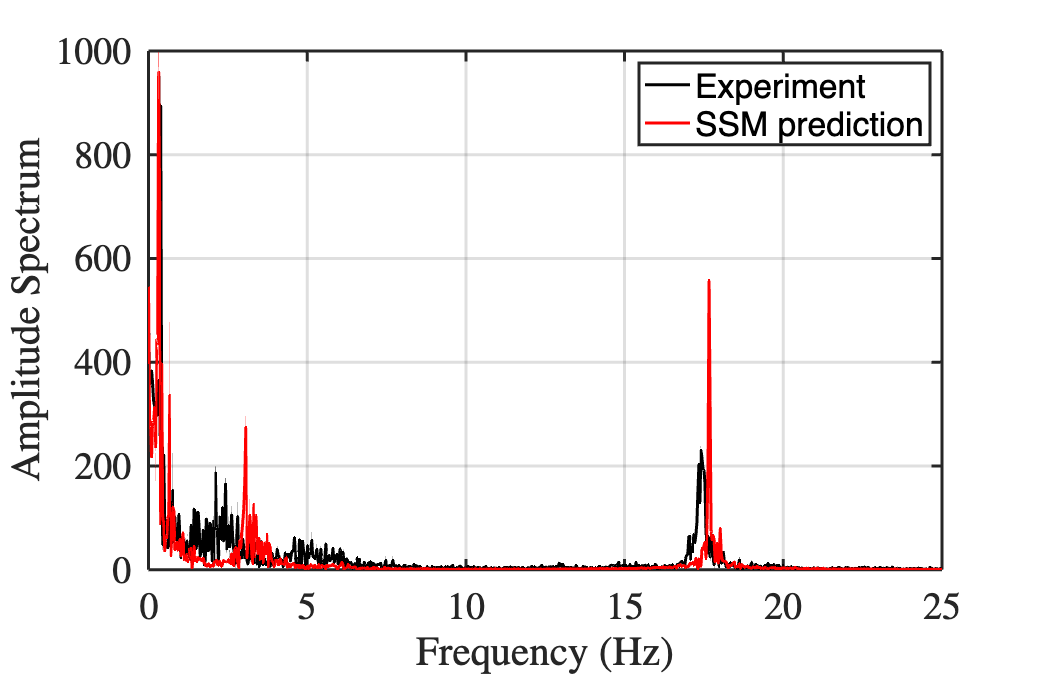


% Frequency spectrum - comparison
y1 = yDataTrunc{indTest(1),2}(1,:);
y2 = yRec{indTest(1),2}(1,:);
dt = yRec{indTest(1),1}(2) - yRec{indTest(1),1}(1);
Fs = 1/dt;

Y1 = fft(y1);
Y2 = fft(y2);
L = numel(y1);
f = Fs*(0:(L/2))/L;

MyCustomFigure(figOpts{:});
plot(f, abs(Y1(1:L/2+1)), 'k', f, abs(Y2(1:L/2+1)), 'r');
xlim([0, 25])
%xlim([0 Fs/2]);
xlabel('Frequency (Hz)');
ylabel('Amplitude Spectrum');
legend('Experiment', 'SSM prediction');
grid on; box on;

## Testing — Probability Density Functions of reduced coordinates

Since trajectory prediction is unreliable for chaotic systems due to their sensitivity to initial conditions, our evaluation focuses on long-term statistics. Specifically, we compare the probability density functions (PDFs) of the reduced coordinates.

Assuming the system is ergodic, we interchange temporal and ensemble averages to estimate the invariant measure of the attractor, following the procedure described in [2].

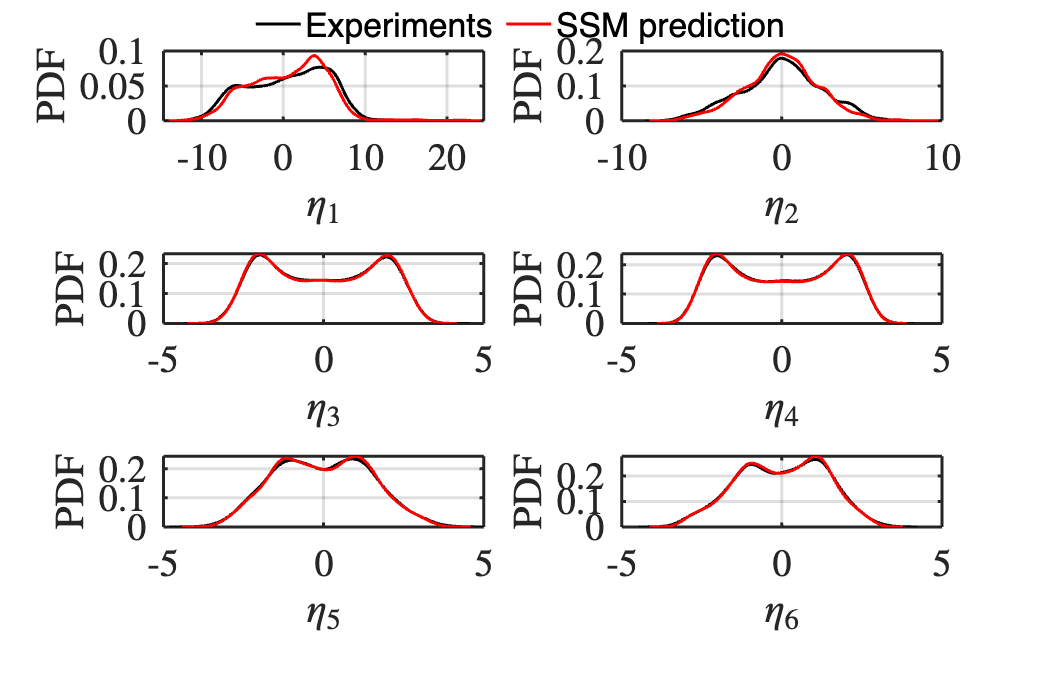

dataExp = [];
dataPred = [];

for idx = indTrain
    dataExp  = [dataExp, etaDataTrunc{idx,2}(:,1:end-1)];
    dataPred = [dataPred, etaRec{idx,2}(:,1:end-1)];
end

legendLabels = {'Experiments','SSM prediction'};
MyCustomFigure(figOpts{:}, 'SubPlot', [3,2]);

for i = 1:6
    hSub = subplot(3,2,i); 

    [fExp,  xiExp]  = ksdensity(dataExp(i,:),  'NumPoints', 200);
    [fRec, xiRec] = ksdensity(dataPred(i,:), 'NumPoints', 200);
    
    h1 = plot(xiExp,  fExp,  'k-'); 
    hold on; grid on;
    h2 = plot(xiRec, fRec, 'r-');
    
    xlabel(sprintf('$\\eta_{%d}$', i));
    ylabel('PDF');
end

lgd = legend([h1, h2], legendLabels, 'Box','off','Orientation','horizontal','NumColumns', 2, 'Position',[0.35 0.94 0.3 0.05]); 

## Visualizing the attractor in the reduced space

Here we visualize the chaotic attractor in the reduced space. 

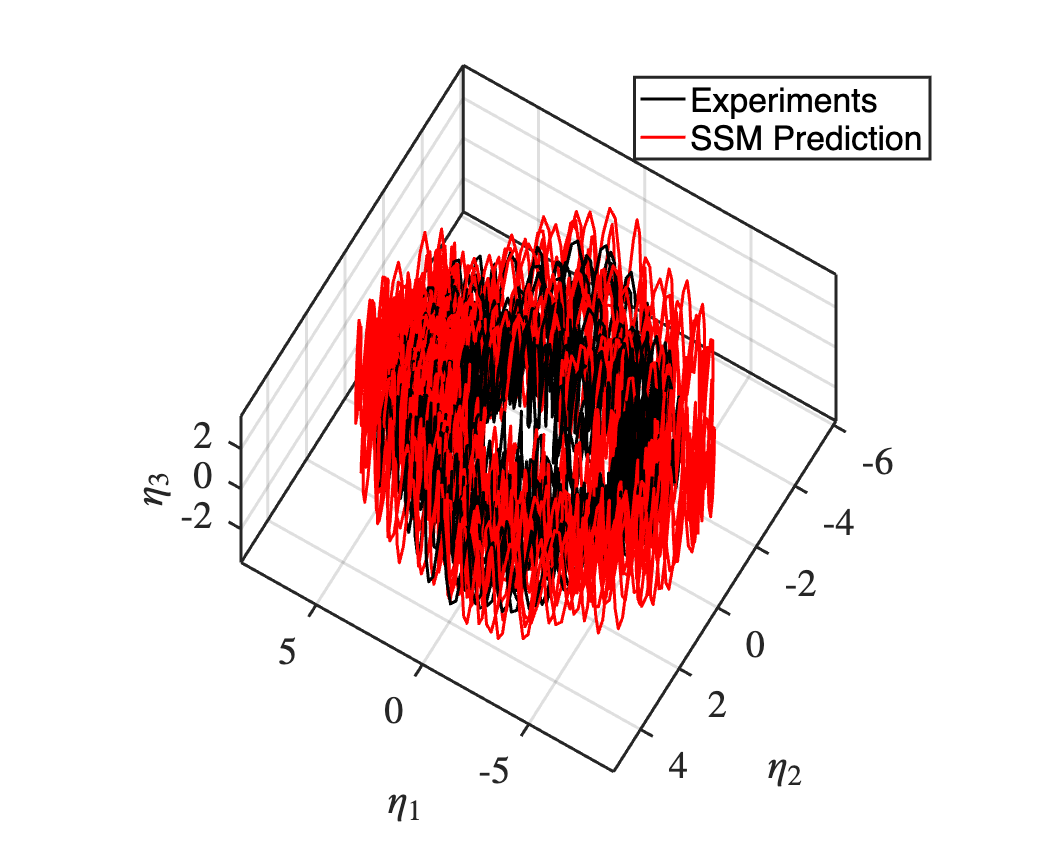

MyCustomFigure(figOpts{:});
set(gcf,'Units','pixels','Position',[100 100 1200 1000]);

[i,j,k] = deal(1,2,3);
t = etaDataTrunc{1,1};
tStartPlot = 3;
startCol = max(find(t >= tStartPlot,1),1);
etaExp = etaDataTrunc{indTest(1),2}(:,startCol:end);;
etaPred = etaRec{indTest(1),2}(:,startCol:end);;

ax = gca; hold(ax,'on'); grid(ax,'on');
h1 = plot3(ax,etaExp(1,:),etaExp(2,:),etaExp(3,:),'k-');
h2 = plot3(ax,etaPred(1,:),etaPred(2,:),etaPred(3,:),'r-');

xlabel(ax,sprintf('$\\eta_{%d}$',i));
ylabel(ax,sprintf('$\\eta_{%d}$',j));
zlabel(ax,sprintf('$\\eta_{%d}$',k));

view([210.82 70.27]); axis(ax,'padded'); axis(ax,'vis3d');
legend(ax,[h1 h2],{'Experiments','SSM Prediction'},'Location','northeast');

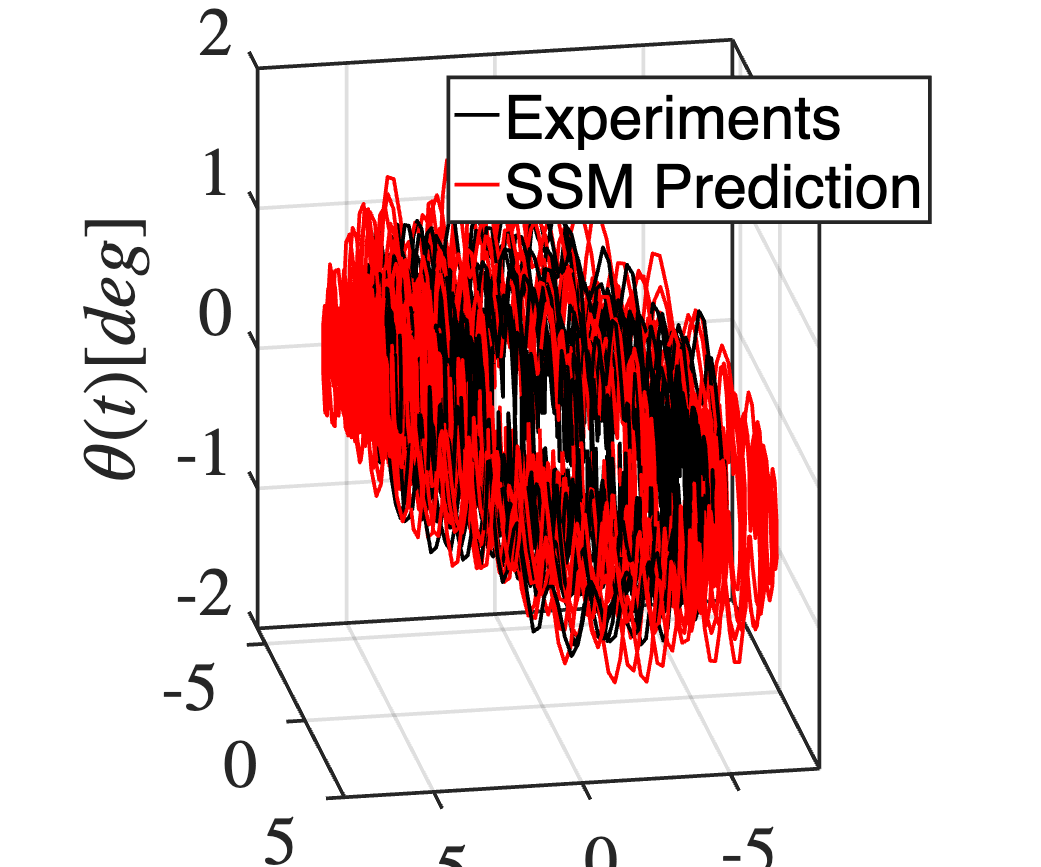

figOpts = { ...
    'Interpreter',     'latex', ...
    'FontName',        'Helvetica', ...
    'FontSizeAxes',    45,   ... % tick labels
    'FontSizeLabels',  45,   ... % axis labels
    'FontSizeTitle',   45,   ... % titles
    'BackgroundColor', 'white', ...
    'Grid',            'on',  ...
    'AxesLineWidth',    2.5, ... %numeric line width for axes box (default: 0.5)
    'PlotLineWidth',    2.5, ...%numeric default line width for plotted data (default: 0.5)
    'Box',             'on'   ...
    'ScreenCoverage', 0.5 %fraction of screen to cover [0,1] (default: 0.8)
};

MyCustomFigure(figOpts{:});
set(gcf,'Units','pixels','Position',[100 100 1200 1000]);

[i,j] = deal(1,2);
t = etaDataTrunc{1,1};
etaExp = etaDataTrunc{indTest(1),2}(:,startCol:end);
etaPred = etaRec{indTest(1),2}(:,startCol:end);
yExp = yDataTrunc{indTest(1),2}(1,startCol:end);
yPred = yRec{indTest(1),2}(1,startCol:end);
tStartPlot = 3;
startCol = max(find(t >= tStartPlot,1),1);

ax = gca; hold(ax,'on'); grid(ax,'on');
h1 = plot3(ax,etaExp(i,:),etaExp(j,:),yExp,'k-');
h2 = plot3(ax,etaPred(i,:),etaPred(j,:),yPred,'r-');

xlabel(ax,sprintf('$\\eta_{%d}$',i));
ylabel(ax,sprintf('$\\eta_{%d}$',j));
zlabel(ax,sprintf('$\\theta(t) [deg]$',k));

view(ax, 170, 20); axis(ax,'padded'); axis(ax,'vis3d');
legend(ax,[h1 h2],{'Experiments','SSM Prediction'},'Location','northeast');

xlim(ax, [-8 8]);
ylim(ax, [-6 5]);
zlim(ax, [-2 2]);

## Lyapunov Exponent estimation 

We estimate the Lyapunov exponent using the same procedure, but now relying solely on experimentally obtained trajectories, for which the initial conditions cannot be precisely controlled. Consequently, the computation is performed using the available trajectories as they are. 

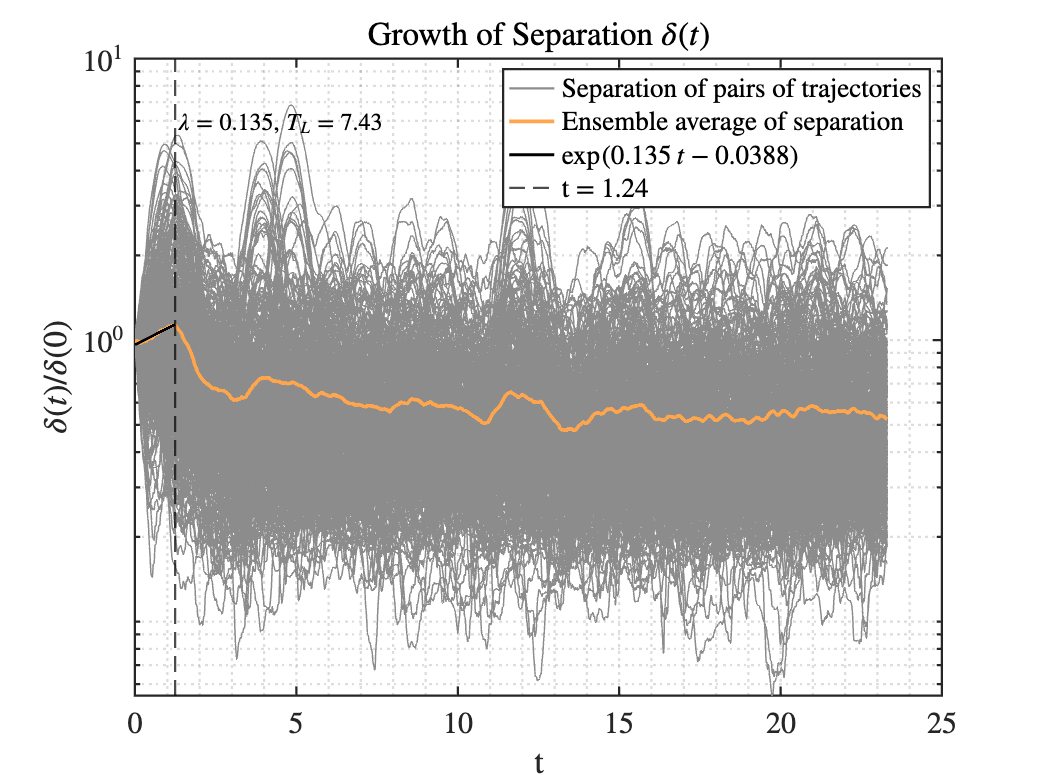

ans = 0.1346

for ii = 1:size(yDataTrunc,1)
    yDataTrunc{ii,1} = yDataTrunc{ii,1} - yDataTrunc{ii,1}(1);
end

LyapunovExponentInteractive(yDataTrunc, 1.24)

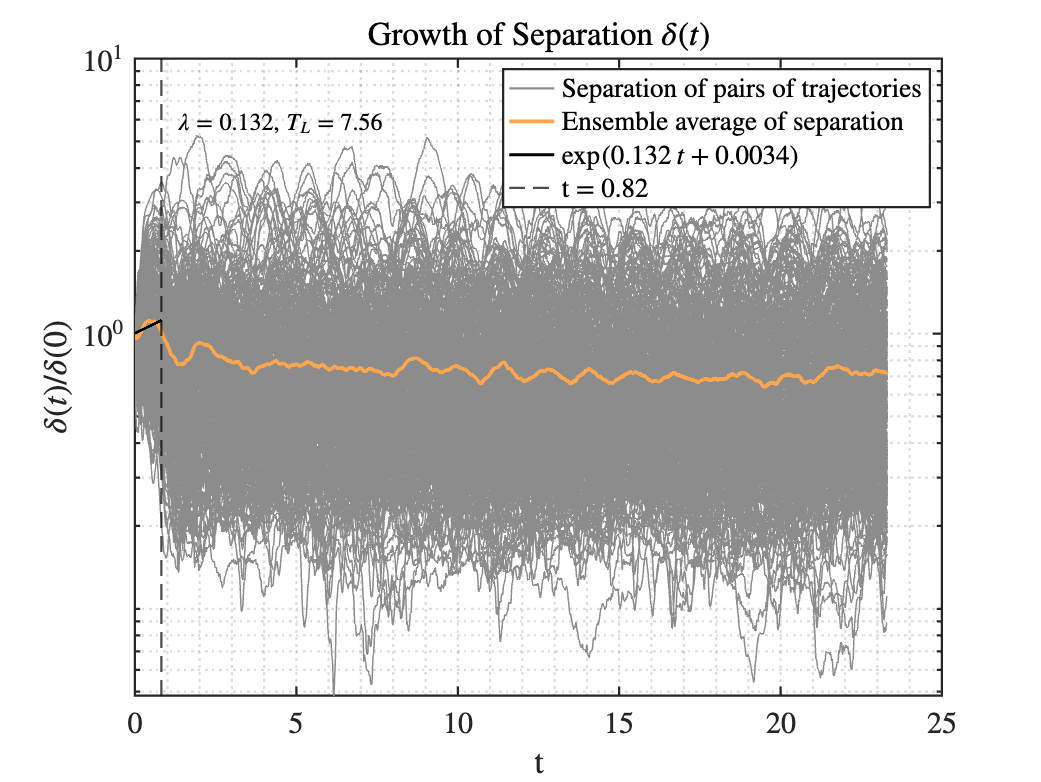

ans = 0.1323



for ii = 1:size(yRec,1)
    yRec{ii,1} = yRec{ii,1} - yRec{ii,1}(1);
end
LyapunovExponentInteractive(yRec, 0.82)

%Save structs
save(fullfile(folder,'IMInfo.mat'),'IMInfo');
save(fullfile(folder,'rbfInterpolated.mat'),'rbfInterpolator');